% IO test
base_path = fullfile('Z:/Data/Processed/2023-10-01-Jiahao-Test/');
data_path = fullfile(base_path, 'CNS_Well07/');
output_path = fullfile('Z:/Data/Analyzed/2023-10-01-Jiahao-Test/CNS_Well07/02_pp');

current_fov = 'tile_1';
useGPU = false;
sdata = STARMapDataset(data_path, output_path, 'useGPU', useGPU);
sdata = sdata.LoadRawImages('sub_dir', current_fov);
sdata = sdata.SwapChannels;
sdata = sdata.EnhanceContrast("min-max"); 
sdata = sdata.HistEqualize; 

% for r=1:sdata.Nround
%     sdata.rawImages{r} = gpuArray(sdata.rawImages{r});
% end

sdata = sdata.MorphRecon;
sdata = sdata.Tophat;

sdata = sdata.Projection('image_slot', "raw");

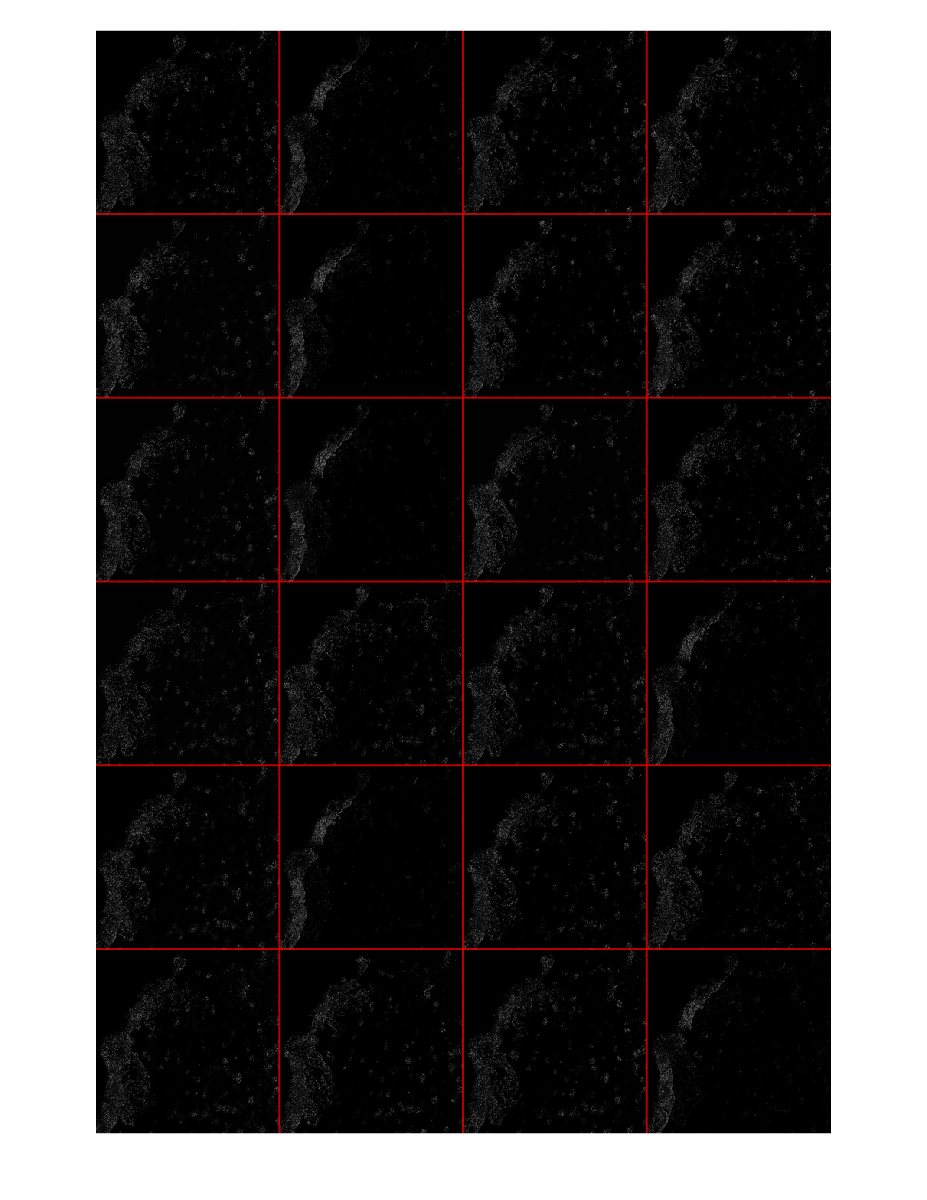

sdata = sdata.ViewProjection('image_slot', "raw");

% I = imread('pout.tif');
I = sdata.rawImages{1}(:,:,:,1);
a = stretchlim(I, 0)
b = min(a(1, :))
c = max(a(2, :))
% stretchlim(I)
I_after = imadjustn(I, [double(b) double(c)]);
% max(I_after, [], 'all')
% min(I_after, [], 'all')
% I_eq = imhistmatch(I, I_after);
% figure
% imshowpair(I, I_after, 'montage');
% figure
% imshowpair(I, I_eq, 'montage');

defaultDict(1).wavelength = 488;
defaultDict(1).id = "ch00";
defaultDict(2).wavelength = 594;
defaultDict(2).id = "ch01";
defaultDict(3).wavelength = 546;
defaultDict(3).id = "ch03";
defaultDict(4).wavelength = 647;
defaultDict(4).id = "ch04";
a = {defaultDict(:).id}

a = containers.Map()
a('test') = [1 2];
a